# БПФ для неравномерно расположенных точек

Данный скрипт использует только ядро **MATLAB**

Создадим сигнал `X,` взятый в неравномерные интервалы на оси времени `t`. 

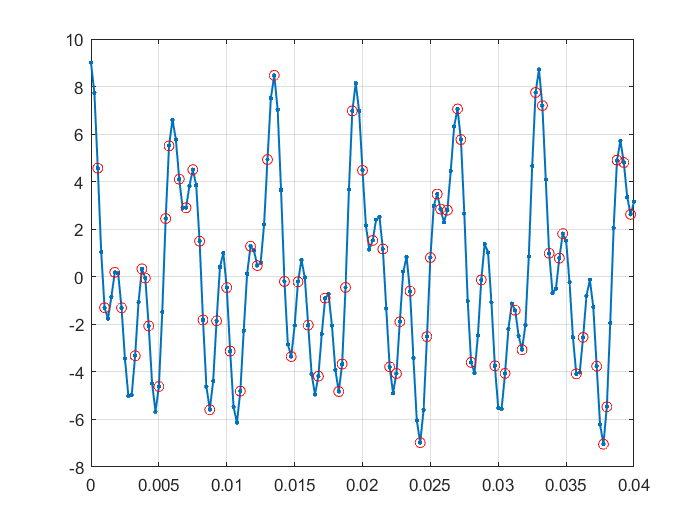

fs = 4000;
t = (0:1/fs:1 - 1/fs)';
n = length(t);

X = 4*cos(2*pi*150*t) +...
    2*cos(2*pi*304*t) +...
    3*cos(2*pi*516*t);

plot(t,X,'LineWidth',1,'Marker','.')
xlim([0 0.04])
hold on

[Xmissing,tmissing,ridx] = helperRandomMissing(X,t,2);
nmissing = length(Xmissing);

plot(tmissing,Xmissing,'ro')
grid
hold off

Оценим разброс значений разницы во временных интервалах:

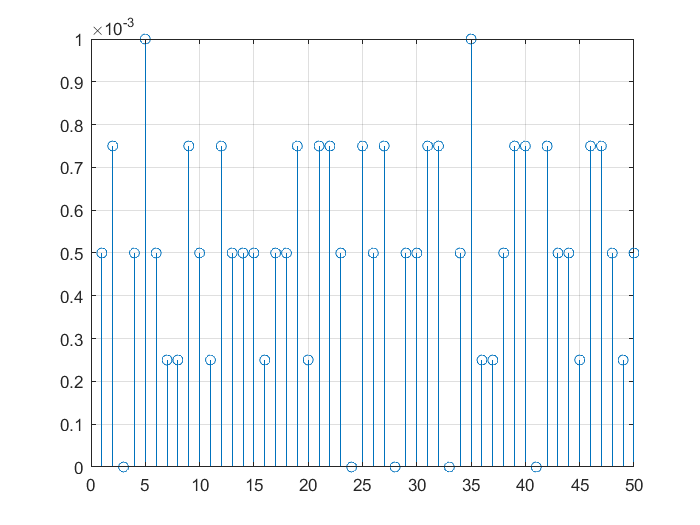

stem(diff(tmissing))
grid
xlim([0 50])

Оценим спектр исходного сигнала равномерным БПФ (функцией **fft)**, а также спектр неравномерного сигнала  функцией **nufft**:

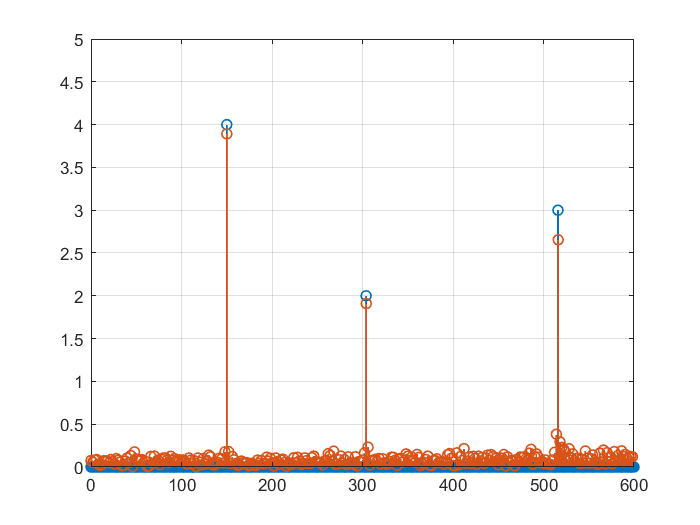

Y = fft(X)/n;

SpectrumX = 2*abs(Y);

m = length(Y);  
ff = (0:m-1)*fs/m;

stem(ff,SpectrumX,'LineWidth',1)
xlim([0 600])
ylim([0 5])
grid

hold on

nuY = nufft(Xmissing,ridx) / nmissing;

nuSpectrumX = 2*abs(nuY);


num = length(nuY);  
nuff = (0:num-1)*fs/num;

stem(nuff,nuSpectrumX,'LineWidth',1)

hold off